clear all;
clc; clf;


Y = [108.495, 106.384, 105.743, 103.111, 99.957, 99.975, 96.943, ...
95.329, 93.231, 91.657, 88.387, 86.353, 85.421, 83.281, 81.987,...
78.835, 78.129, 76.471, 74.964, 73.132, 71.404, 67.943, 67.589,...
66.169, 64.248, 63.617, 62.224, 60.353, 59.656, 58.227, 57.058,...
54.492, 52.386, 52.959, 51.738, 50.826, 49.829, 47.739 47.489 45.903,...
44.330, 44.588, 43.788, 41.052, 41.937, 40.338, 39.946, 38.230, 37.979,...
37.185, 35.741, 35.183, 34.149, 33.157, 32.989, 32.912, 32.166, ...
31.190, 30.855, 29.402]

Y =   108.4950  106.3840  105.7430  103.1110   99.9570   99.9750   96.9430   95.3290   93.2310   91.6570   88.3870   86.3530   85.4210   83.2810   81.9870   78.8350   78.1290   76.4710   74.9640   73.1320   71.4040   67.9430   67.5890   66.1690   64.2480   63.6170   62.2240   60.3530   59.6560   58.2270   57.0580   54.4920   52.3860   52.9590   51.7380   50.8260   49.8290   47.7390   47.4890   45.9030   44.3300   44.5880   43.7880   41.0520   41.9370   40.3380   39.9460   38.2300   37.9790   37.1850



% i = linspace(0, 59, 60)
% T = 6 + 60*i

T = 6 + 60*(0:59) % lijst met elementen 0 -> 59

T =            6          66         126         186         246         306         366         426         486         546         606         666         726         786         846         906         966        1026        1086        1146        1206        1266        1326        1386        1446        1506        1566        1626        1686        1746        1806        1866        1926        1986        2046        2106        2166        2226        2286        2346        2406        2466        2526        2586        2646        2706        2766        2826        2886        2946



scatter(T, Y)

Exponentiele daling, nu fitten we hierdoor met polyfit()

% polyfit(T ,Y, 3)
points = [1, 20 ,40, 60]

points =      1    20    40    60


[p, ~, mu] = polyfit(T(points), Y(points), 3) % Delete tweede output

p =     0.1661    8.4841  -34.4868   57.8670


mu = 1.0e+03 *

    1.7610
    1.5261



x = 6:3546

x =      6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55


y = polyval(p, x, [], mu) % lege lijst om input leeg te laten

y =   108.4950  108.4601  108.4251  108.3902  108.3552  108.3203  108.2854  108.2505  108.2156  108.1807  108.1458  108.1109  108.0760  108.0412  108.0063  107.9715  107.9366  107.9018  107.8669  107.8321  107.7973  107.7625  107.7277  107.6929  107.6581  107.6233  107.5885  107.5537  107.5190  107.4842  107.4495  107.4147  107.3800  107.3452  107.3105  107.2758  107.2411  107.2064  107.1717  107.1370  107.1023  107.0676  107.0330  106.9983  106.9636  106.9290  106.8943  106.8597  106.8251  106.7904


hold on
plot(x, y)
hold off

jeej, da werkt voor graad 3.

Voor hogeregraads veeltermen werkt dit niet (de polynoom begint te oscilleren om alle punten te fitten)

error_i = f(x_i) - y_i    => error is SUM(error_i) (dat wil je minimaliseren)

we weten dat f = Ac

om te minimaliseren gebruik je de tweenorm (inproduct): (Ac-y)^T . (Ac-y) <=> 2A^TAc - 2A^Ty = c => c = (A^T A)^-1 * y

d = 3

d = 3

for i = 1: d+1
    A(:, i) = T.^(i-1);
end
c = flipud(A\Y')

c =    -0.0000
    0.0000
   -0.0374
  109.7702



y2 = polyval(c, x)

y2 =   109.5458  109.5085  109.4711  109.4338  109.3964  109.3591  109.3218  109.2845  109.2472  109.2099  109.1726  109.1353  109.0980  109.0608  109.0235  108.9863  108.9491  108.9119  108.8746  108.8374  108.8003  108.7631  108.7259  108.6887  108.6516  108.6144  108.5773  108.5402  108.5031  108.4660  108.4289  108.3918  108.3547  108.3176  108.2806  108.2435  108.2065  108.1694  108.1324  108.0954  108.0584  108.0214  107.9844  107.9475  107.9105  107.8735  107.8366  107.7996  107.7627  107.7258


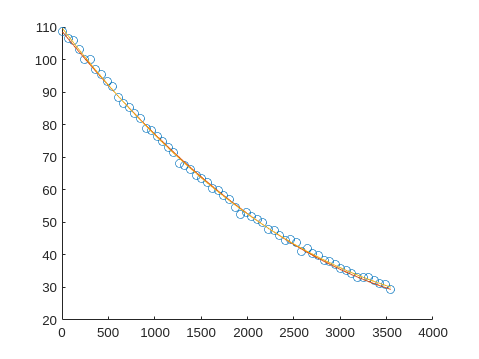

hold on
plot(x, y2)
hold off

conditie (again) voor matrix 1

xsolU = randn(5,1); % De oplossing, die wij opleggen
U = orth(randn(5));
bU = U*xsolU; % De rechterhandzijde die overeenkomt met xsolU

cond(U)

ans = 1.0000

norm(U - xsolU)/norm(U)

ans = 4.7038

maatrix2

xsolH = randn(10,1);
H = hilb(10);
bH = H*xsolH;

norm(H - xsolH)/norm(H)

ans = 6.7167


xsolG = randn(25,1);
r = 0.95;
G = gfpp(25,r);
bG = G*xsolG;

norm(G - xsolG)/norm(G)

ans = 1.7030


xsolW = randn(250,1);
W = randn(250);
bW = W*xsolW;

norm(W - xsolW)/norm(W)

ans = 8.0692